clear; 
clc; 
close all;

%% Datos del problema 
nombres = {'Kit de Primeros Auxilios Avanzado','Desfibrilador Portátil', ...
    'Manta Térmica de Emergencia (Pack x50)','Pastillas Purificadoras de Agua (Caja)', ...
    'Raciones de Comida MRE (Pack x20)','Generador Eléctrico Pequeño', ...
    'Kit de Herramientas de Rescate','Tienda de Campaña Familiar', ...
    'Linternas Recargables (Pack x15)','Antibióticos de Amplio Espectro (Caja)', ...
    'Radio de Comunicación Satelital','Suero Fisiológico Flujo Alto (Caja)', ...
    'Kit de Costura y Sutura Médica','Oxímetro y Tensiómetro Digital', ...
    'Analgésicos Fuertes (Caja)','Camilla Plegable de Lona', ...
    'Botellas de Agua Mineral (Pack x24)','Kit de Higiene Femenina (Caja)', ...
    'Leche en Polvo Infantil (Caja)','Repelente de Insectos Concentrado', ...
    'Jabón Antiséptico Líquido (Bidón)','Pañales para Bebé (Caja Grande)', ...
    'Combustible para Generador (Bidón)','Ropa de Abrigo Surtida (Caja)', ...
    'Vacunas Críticas contra Hepatitis','Impermeables para Lluvia (Pack x30)', ...
    'Bengalas y Señales de Humo','Guantes Quirúrgicos (Caja x500)', ...
    'Linternas de Cabeza para Rescatistas','Kit de Intubación Pediátrica', ...
    'Kit Quirúrgico Menor','Camillas de Inmovilización Espinal', ...
    'Desinfectante de Superficies Médicas','Equipos de Protección EPP (Caja)', ...
    'Insulina y Nevera de Transporte','Baterías Externas Powerbank (Pack)', ...
    'Kit de Ferulización de Miembros','Megáfono a Baterías', ...
    'Kit de Herramientas Multiusos','Antivenenos para Mordedura de Serpiente', ...
    'Apósitos y Gasas Estériles (Caja)','Máscaras de Oxígeno con Reservorio', ...
    'Alcohol Isopropílico (Bidón)','Suero Oral en Polvo (Caja x100)', ...
    'Sacos de Dormir Térmicos','Kit Tratamiento de Quemaduras', ...
    'Unidad de Purificación Filtración Portátil','Alimentos Deshidratados Energéticos', ...
    'Estufas Portátiles de Gas','Kit de Iluminación Perimetral LED'};

valores = [91 24 13 45 41 38 27 23 96 79 21 85 64 14 13 21 37 39 74 87 ...
           13 81 35 93 99 79 63 38 67 85 45 10 30 99 64 53 45 29 37 53 ...
           23 21 58 22 55 54 87 43 15 68];

pesos = [39 12 29 10 40 23 45 44 28 41 17 50 9 7 47 19 23 10 19 11 ...
         29 22 34 45 28 15 28 27 18 47 22 49 48 46 9 43 45 15 39 20 ...
         15 34 29 22 45 49 40 19 48 25];

capacidad = 591;
n = numel(valores);

%% Parámetros 
T0 = 100;    %Temperatura inicial
maxIter = 1000;  %Maximo de iteracciones


%% Convergencia exponencial 
alphaExp = 0.99; % factor de decaimiento
[Mejor_exp,MejorQ_exp, hist_exp, histT_exp] = ...
    Enfriamiento_Simulado(valores, pesos, capacidad, T0, maxIter, 'exponencial', alphaExp);

%% Convergencia lineal 
[Mejor_lin, MejorQ_lin, hist_lin, histT_lin] = ...
    Enfriamiento_Simulado(valores, pesos, capacidad, T0, maxIter, 'lineal', []);

%% Resultados
fprintf('Resultados Simulated Annealing ===\n\n');

Resultados Simulated Annealing ===




fprintf('--- Regla de convergencia EXPONENCIAL ---\n');

--- Regla de convergencia EXPONENCIAL ---


fprintf('Mejor utilidad total: %d\n', MejorQ_exp);

Mejor utilidad total: 1648


fprintf('Peso total usado: %d / %d kg\n', sum(pesos(Mejor_exp==1)), capacidad);

Peso total usado: 591 / 591 kg


fprintf('Suministros seleccionados (ID): %s\n\n', mat2str(find(Mejor_exp==1)));

Suministros seleccionados (ID): [1 4 9 10 12 13 18 19 20 22 24 25 26 27 29 30 31 34 35 43 47 50]




fprintf('--- Regla de convergencia LINEAL ---\n');

--- Regla de convergencia LINEAL ---


fprintf('Mejor utilidad total: %d\n', MejorQ_lin);

Mejor utilidad total: 1556


fprintf('Peso total usado: %d / %d kg\n', sum(pesos(Mejor_lin==1)), capacidad);

Peso total usado: 584 / 591 kg


fprintf('Suministros seleccionados (ID): %s\n\n', mat2str(find(Mejor_lin==1)));

Suministros seleccionados (ID): [1 2 6 9 10 11 12 13 18 19 20 22 25 26 27 29 30 31 34 35 40 45 50]




fprintf('Detalle de la mejor solución (mayor utilidad de las dos):\n');

Detalle de la mejor solución (mayor utilidad de las dos):


if MejorQ_exp >= MejorQ_lin
    mejor = Mejor_exp; tag = 'EXPONENCIAL';
else
    mejor = Mejor_lin; tag = 'LINEAL';
end

fprintf('(Ganadora: regla %s)\n', tag);

(Ganadora: regla EXPONENCIAL)


idxSel = find(mejor==1);
for k = idxSel
    fprintf('  ID %2d | %-45s | Valor: %3d | Peso: %2d kg\n', k, nombres{k}, valores(k), pesos(k));
end

  ID  1 | Kit de Primeros Auxilios Avanzado             | Valor:  91 | Peso: 39 kg
  ID  4 | Pastillas Purificadoras de Agua (Caja)        | Valor:  45 | Peso: 10 kg
  ID  9 | Linternas Recargables (Pack x15)              | Valor:  96 | Peso: 28 kg
  ID 10 | Antibióticos de Amplio Espectro (Caja)        | Valor:  79 | Peso: 41 kg
  ID 12 | Suero Fisiológico Flujo Alto (Caja)           | Valor:  85 | Peso: 50 kg
  ID 13 | Kit de Costura y Sutura Médica                | Valor:  64 | Peso:  9 kg
  ID 18 | Kit de Higiene Femenina (Caja)                | Valor:  39 | Peso: 10 kg
  ID 19 | Leche en Polvo Infantil (Caja)                | Valor:  74 | Peso: 19 kg
  ID 20 | Repelente de Insectos Concentrado             | Valor:  87 | Peso: 11 kg
  ID 22 | Pañales para Bebé (Caja Grande)               | Valor:  81 | Peso: 22 kg
  ID 24 | Ropa de Abrigo Surtida (Caja)                 | Valor:  93 | Peso: 45 kg
  ID 25 | Vacunas Críticas contra Hepatitis             | Valor:  99 | Peso: 28 kg
  ID

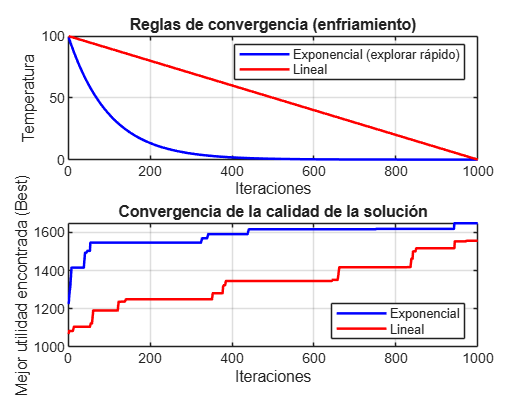


%%  Gráficas comparativas 
figure('Name','Comparación de reglas de convergencia - Simulated Annealing','Color','w');

subplot(2,1,1);
plot(1:maxIter, histT_exp, 'b-', 'LineWidth', 1.5); hold on;
plot(1:maxIter, histT_lin, 'r-', 'LineWidth', 1.5);
xlabel('Iteraciones'); ylabel('Temperatura');
title('Reglas de convergencia (enfriamiento)');
legend('Exponencial (explorar rápido)', 'Lineal', 'Location','northeast');
grid on;

subplot(2,1,2);
plot(1:maxIter, hist_exp, 'b-', 'LineWidth', 1.5); hold on;
plot(1:maxIter, hist_lin, 'r-', 'LineWidth', 1.5);
xlabel('Iteraciones'); ylabel('Mejor utilidad encontrada (Best)');
title('Convergencia de la calidad de la solución');
legend('Exponencial', 'Lineal', 'Location','southeast');
grid on;



%% Funciones

function [Mejor, MejorQ, historico, historico_T] = Enfriamiento_Simulado(...
    valores, pesos, capacidad, T0, maxIter, Tipo, alpha)

    n = numel(valores);
    S = zeros(1,n);     %Solución inicial candidata
    order = randperm(n);
    pesoActual = 0;
    for i = order
        if pesoActual + pesos(i) <= capacidad
            S(i) = 1;
            pesoActual = pesoActual + pesos(i);
        end
    end

    Mejor = S;
    t = T0;

    historico = zeros(1,maxIter);
    historico_T    = zeros(1,maxIter);

    for iter = 1:maxIter

        % R <- Tweak(Copy(S))
        R = tweak(S, pesos, capacidad);

        qR = quality(R, valores);
        qS = quality(S, valores);
  
        % if Quality(R) > Quality(S) or rand < exp((Quality(R)-Quality(S))/t)
        if qR > qS || rand() < exp((qR - qS)/max(t,1e-6))
            S = R;
        end

        %Disminución de t según la regla de convergencia elegida
        switch Tipo
            case 'exponencial'
                t = T0 * alpha^iter; %Enfriamiento exponencial
            case 'lineal'
                t = max(T0 * (1 - iter/maxIter), 0); %Enfriamiento lineal
        end

        if quality(S, valores) > quality(Mejor, valores)
            Mejor = S;
        end

        historico(iter) = quality(Mejor, valores);
        historico_T(iter) = t;
    end

    MejorQ = quality(Mejor, valores);
end

function q = quality(sol, valores)
    q = sum(valores(sol==1));
end

function R = tweak(S, pesos, capacidad)
    n = numel(S);
    R = S;
    idx = randi(n);
    R(idx) = 1 - R(idx);

    while sum(pesos(R==1)) > capacidad
        seleccionados = find(R==1);
        if isempty(seleccionados)
            break;
        end
        quitar = seleccionados(randi(numel(seleccionados)));
        R(quitar) = 0;
    end
end
